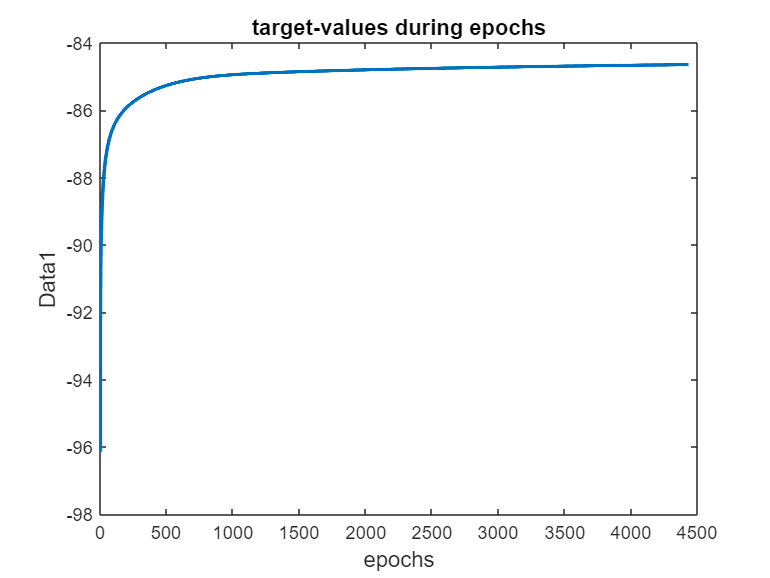

rng(1)
[G1,N0_1,P_max_1]=loading('a1.mat');
[G2,N0_2,P_max_2]=loading('a2.mat');
[G3,N0_3,P_max_3]=loading('a3.mat');
[G4,N0_4,P_max_4]=loading('a4.mat');
[G5,N0_5,P_max_5]=loading('a5.mat');

P0 = rand(1,50).';
alpha = 0.01;
[P_optimum1,P_lists1,f_lists1,iterations_Num1] = GA(P0,alpha,G1,N0_1,P_max_1);
[P_optimum2,P_lists2,f_lists2,iterations_Num2] = GA(P0,alpha,G2,N0_2,P_max_2);
[P_optimum3,P_lists3,f_lists3,iterations_Num3] = GA(P0,alpha,G3,N0_3,P_max_3);
[P_optimum4,P_lists4,f_lists4,iterations_Num4] = GA(P0,alpha,G4,N0_4,P_max_4);
P0 = rand(1,500).';
[P_optimum5,P_lists5,f_lists5,iterations_Num5] = GA(P0,alpha,G5,N0_5,P_max_5);


%%% data1



figure(1)
iteration1=1:1:iterations_Num1;
plot(iteration1,f_lists1,'LineWidth',2)
title('target-values during epochs','FontSize',12)
xlabel('epochs','FontSize',12)
ylabel('Data1','FontSize',12)

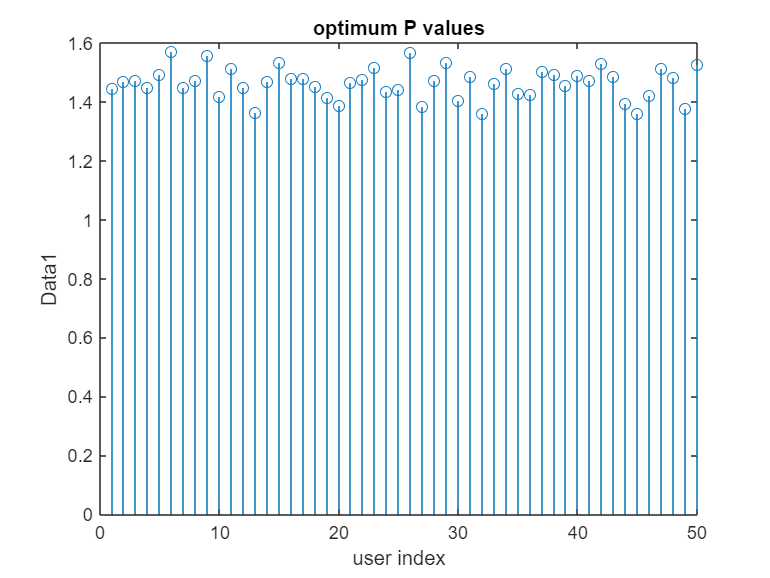


figure(2)
stem(P_optimum1)
title('optimum P values')
xlabel('user index')
ylabel('Data1')

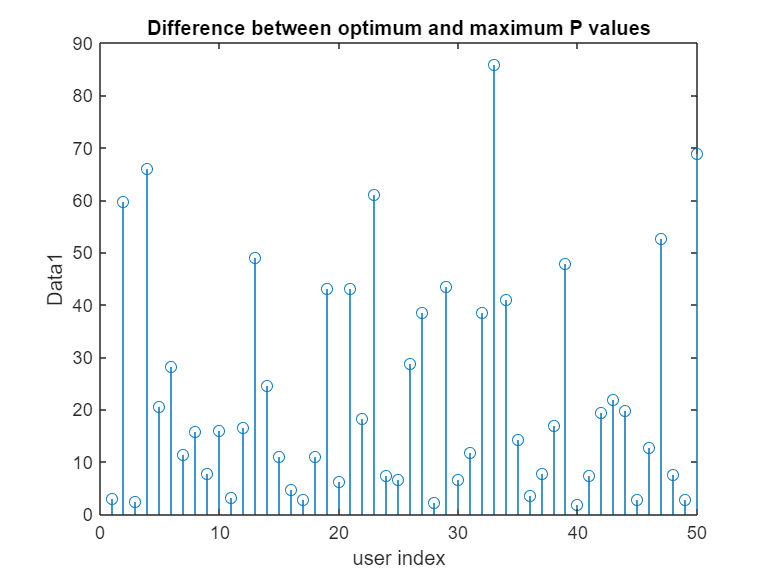



figure(3)
stem(abs(P_optimum1.'-P_max_1))
title('Difference between optimum and maximum P values')
xlabel('user index')
ylabel('Data1')

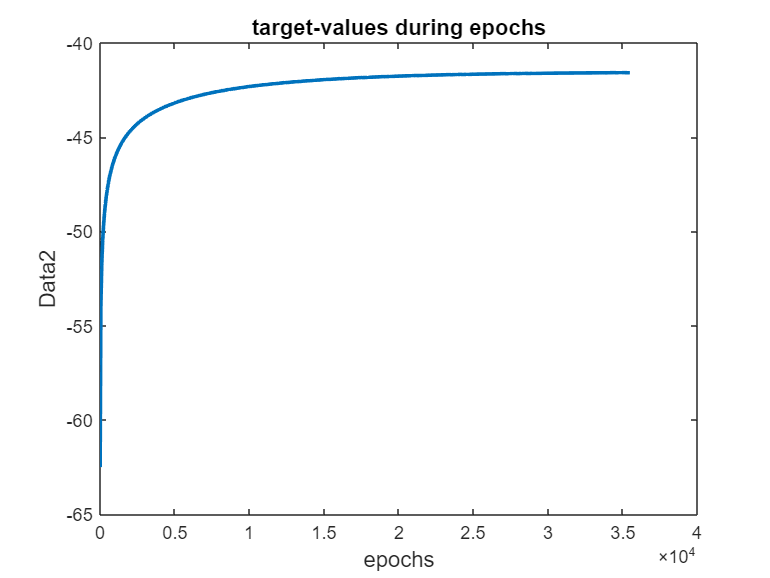



%%% data2


figure(4)
iteration2=1:1:iterations_Num2;
plot(iteration2,f_lists2,'LineWidth',2)
title('target-values during epochs','FontSize',12)
xlabel('epochs','FontSize',12)
ylabel('Data2','FontSize',12)

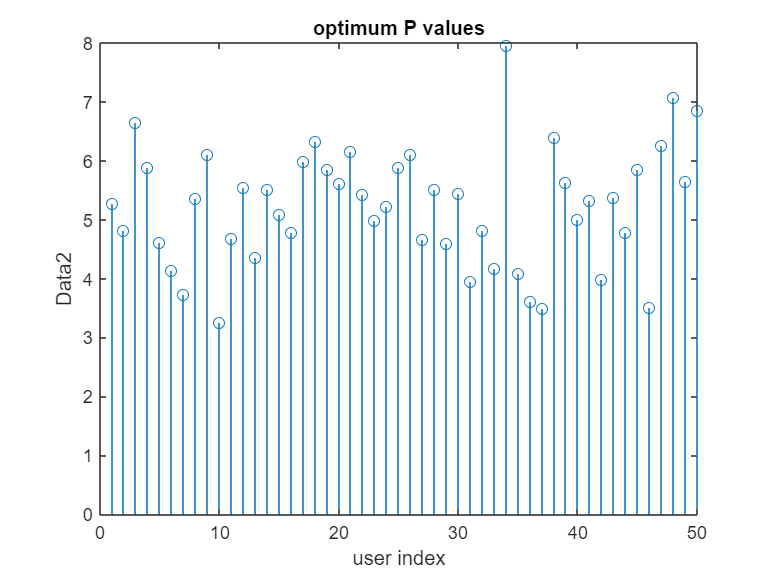


figure(5)
stem(P_optimum2)
title('optimum P values')
xlabel('user index')
ylabel('Data2')

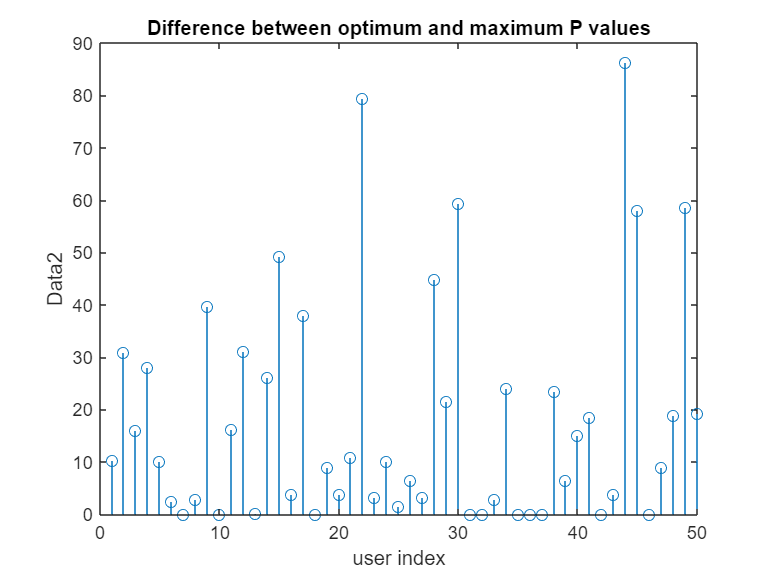


figure(6)
stem(abs(P_optimum2.'-P_max_2))
title('Difference between optimum and maximum P values')
xlabel('user index')
ylabel('Data2')

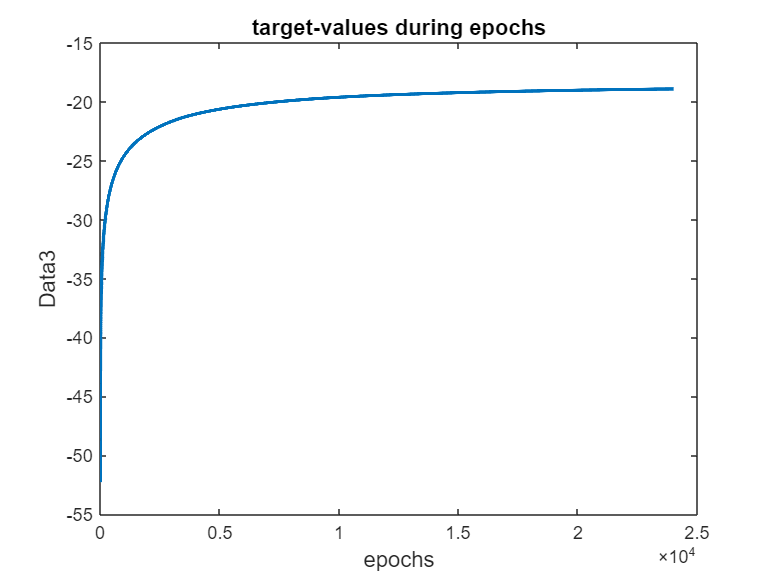


%%% data3




figure(7)
iteration3=1:1:iterations_Num3;
plot(iteration3,f_lists3,'LineWidth',2)
title('target-values during epochs','FontSize',12)
xlabel('epochs','FontSize',12)
ylabel('Data3','FontSize',12)

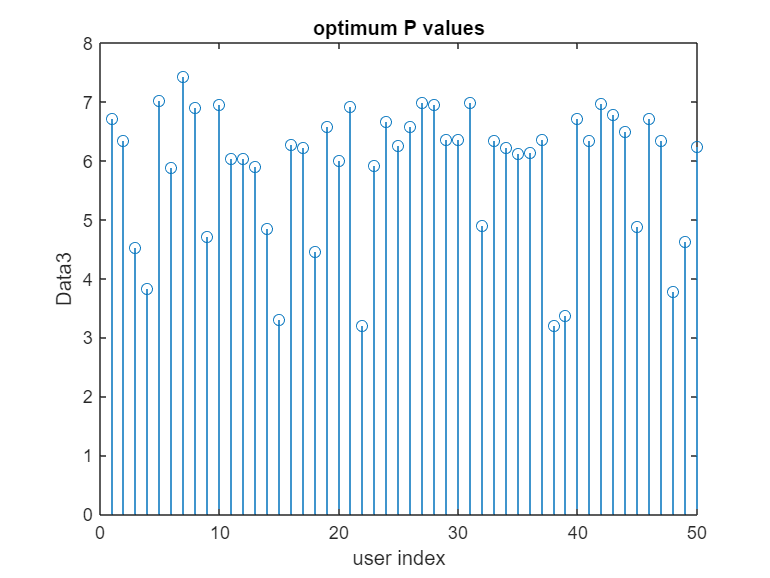

figure(8)
stem(P_optimum3)
title('optimum P values')
xlabel('user index')
ylabel('Data3')

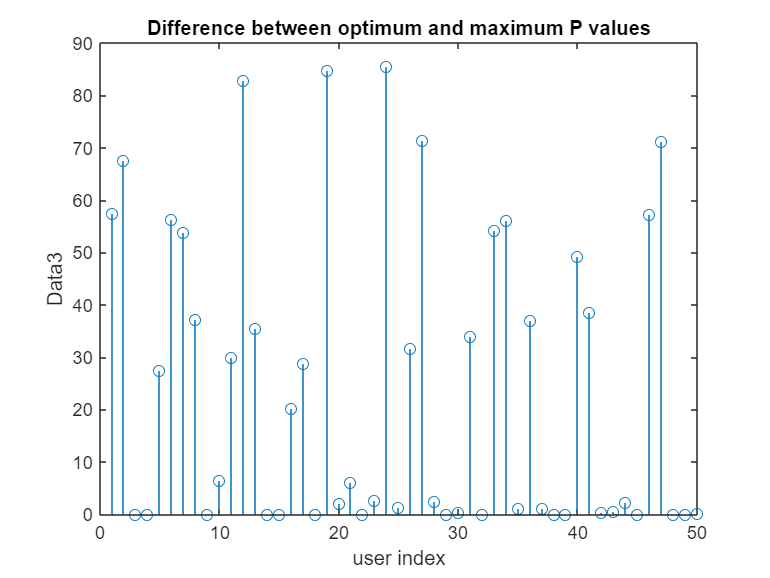


figure(9)
stem(abs(P_optimum3.'-P_max_3))
title('Difference between optimum and maximum P values')
xlabel('user index')
ylabel('Data3')

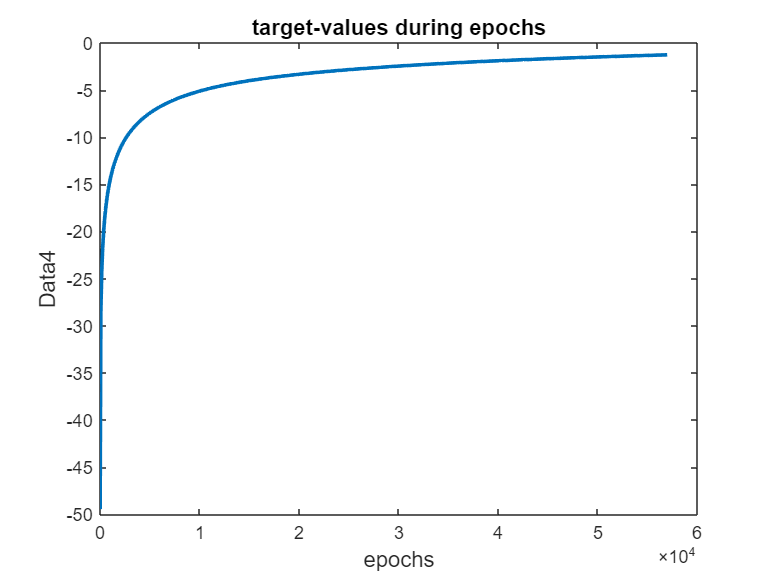


%%% data4



figure(10)
iteration4=1:1:iterations_Num4;
plot(iteration4,f_lists4,'LineWidth',2)
title('target-values during epochs','FontSize',12)
xlabel('epochs','FontSize',12)
ylabel('Data4','FontSize',12)

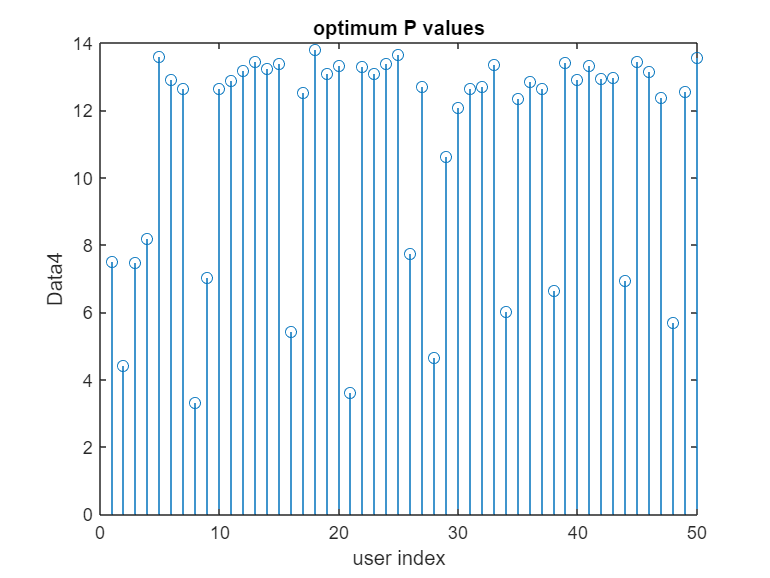


figure(11)
stem(P_optimum4)
title('optimum P values')
xlabel('user index')
ylabel('Data4')

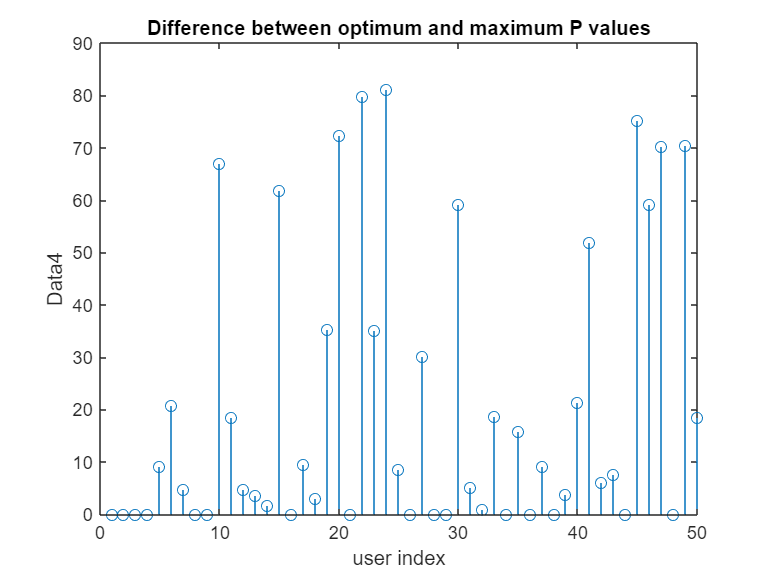


figure(12)
stem(abs(P_optimum4.'-P_max_4))
title('Difference between optimum and maximum P values')
xlabel('user index')
ylabel('Data4')

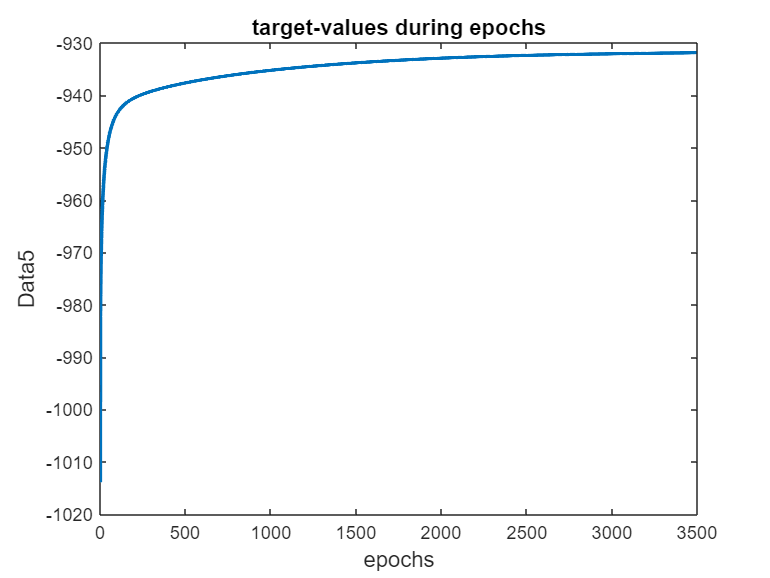



%%% data5

figure(13)
iteration5=1:1:iterations_Num5;
plot(iteration5,f_lists5,'LineWidth',2)
title('target-values during epochs','FontSize',12)
xlabel('epochs','FontSize',12)
ylabel('Data5','FontSize',12)

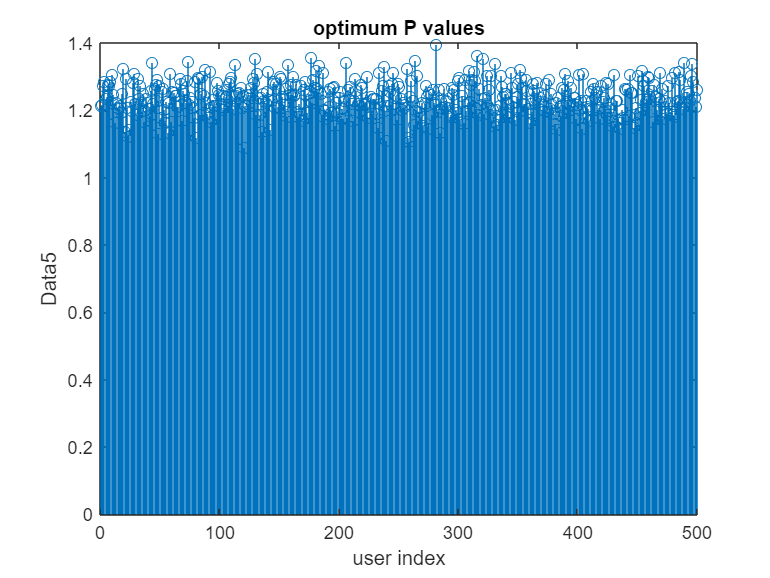


figure(14)
stem(P_optimum5)
title('optimum P values')
xlabel('user index')
ylabel('Data5')

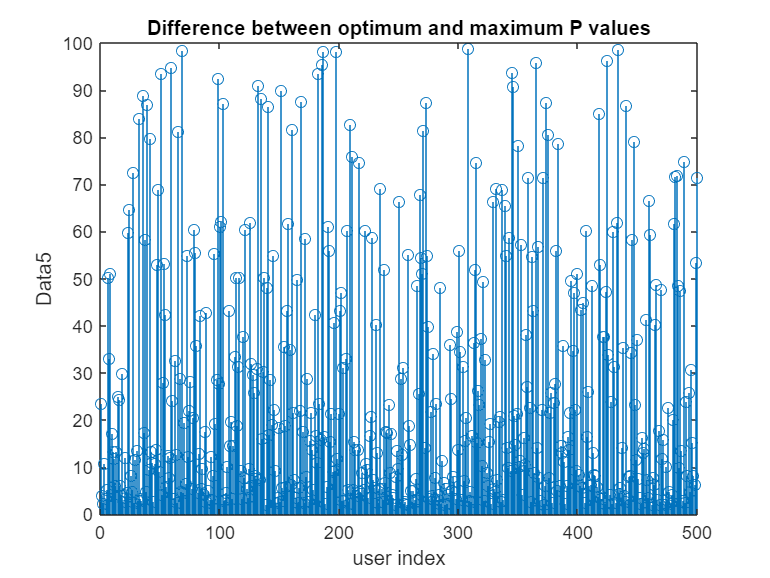


figure(15)
stem(abs(P_optimum5.'-P_max_5))
title('Difference between optimum and maximum P values')
xlabel('user index')
ylabel('Data5')



fvalue_p_opt1=f(P_optimum1,G1,N0_1);
fvalue_p_max1=f(P_max_1,G1,N0_1);
improvement1=fvalue_p_opt1-fvalue_p_max1;
Save_Power1=sum(P_max_1)-sum(P_optimum1);
Iteratation_Num1=iterations_Num1;

fvalue_p_opt2=f(P_optimum2,G2,N0_2);
fvalue_p_max2=f(P_max_2,G2,N0_2);
improvement2=fvalue_p_opt2-fvalue_p_max2;
Save_Power2=sum(P_max_2)-sum(P_optimum2);
Iteratation_Num2=iterations_Num2;

fvalue_p_opt3=f(P_optimum3,G3,N0_3);
fvalue_p_max3=f(P_max_3,G3,N0_3);
improvement3=fvalue_p_opt3-fvalue_p_max3;
Save_Power3=sum(P_max_3)-sum(P_optimum3);
Iteratation_Num3=iterations_Num3;

fvalue_p_opt4=f(P_optimum4,G4,N0_4);
fvalue_p_max4=f(P_max_4,G4,N0_4);
improvement4=fvalue_p_opt4-fvalue_p_max4;
Save_Power4=sum(P_max_4)-sum(P_optimum4);
Iteratation_Num4=iterations_Num4;

fvalue_p_opt5=f(P_optimum5,G5,N0_5);
fvalue_p_max5=f(P_max_5,G5,N0_5);
improvement5=fvalue_p_opt5-fvalue_p_max5;
Save_Power5=sum(P_max_5)-sum(P_optimum5);
Iteratation_Num5=iterations_Num5;

disp(['f-optimum1: ',num2str(fvalue_p_opt1)])

f-optimum1: -84.6439


disp(['f-max1: ',num2str(fvalue_p_max1)])

f-max1: -92.5384


disp(['improvement1: ',num2str(improvement1)])

improvement1: 7.8945


disp(['Save_Power1: ',num2str(Save_Power1)])

Save_Power1: 1143.5912


disp(['Iteratation_Num1: ',num2str(Iteratation_Num1)])

Iteratation_Num1: 4433



disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp(['f-optimum2: ',num2str(fvalue_p_opt2)])

f-optimum2: -41.5764


disp(['f-max2: ',num2str(fvalue_p_max2)])

f-max2: -48.8192


disp(['improvement2: ',num2str(improvement2)])

improvement2: 7.2429


disp(['Save_Power2: ',num2str(Save_Power2)])

Save_Power2: 900.3418


disp(['Iteratation_Num2: ',num2str(Iteratation_Num2)])

Iteratation_Num2: 35480



disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp(['f-optimum3: ',num2str(fvalue_p_opt3)])

f-optimum3: -18.9034


disp(['f-max3: ',num2str(fvalue_p_max3)])

f-max3: -25.7855


disp(['improvement3: ',num2str(improvement3)])

improvement3: 6.8821


disp(['Save_Power3: ',num2str(Save_Power3)])

Save_Power3: 1193.3562


disp(['Iteratation_Num3: ',num2str(Iteratation_Num3)])

Iteratation_Num3: 24003



disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp(['f-optimum4: ',num2str(fvalue_p_opt4)])

f-optimum4: -1.2624


disp(['f-max4: ',num2str(fvalue_p_max4)])

f-max4: 0.68612


disp(['improvement4: ',num2str(improvement4)])

improvement4: -1.9485


disp(['Save_Power4: ',num2str(Save_Power4)])

Save_Power4: 1038.7446


disp(['Iteratation_Num4: ',num2str(Iteratation_Num4)])

Iteratation_Num4: 56966



disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp(['f-optimum5: ',num2str(fvalue_p_opt5)])

f-optimum5: -931.8648


disp(['f-max5: ',num2str(fvalue_p_max5)])

f-max5: -1031.2882


disp(['improvement5: ',num2str(improvement5)])

improvement5: 99.4234


disp(['Save_Power5: ',num2str(Save_Power5)])

Save_Power5: 13205.5902


disp(['Iteratation_Num5: ',num2str(Iteratation_Num5)])

Iteratation_Num5: 3494



disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function [f_res,Ri,SINR_vector]=f(P,G,N0)
signal=0;
for i=1:1:length(P)
signal=G(i,i)*P(i);
ISI=0;
for j=1:1:length(P)
if i ~=j
ISI=ISI+G(i,j)*P(j);
end
end
SINR(i)=signal/(N0(i)+ISI);
end
SINR_vector=SINR;
Ri=log10(1+SINR);
f_res=sum(log10(Ri));
end
function grad=gradient_calc(P,G,N0)
[~,Ri,SINR_vector]=f(P,G,N0);
for i=1:1:length(P)
collector=(SINR_vector(i)/((log(10)^2)*Ri(i)*(1+SINR_vector(i))))/P(i);
for k=1:1:length(P)
if i~=k
collector=collector+(1/((log(10)^2)*Ri(k)*(1+SINR_vector(k))))*((-SINR_vector(k)^2*G(k,i))/(G(k,k)*P(k)));
end
end
grad(i)=collector;
end
end
function [G,N0,P_max]=loading(filename)
G=load(filename).G;
N0=load(filename).N0;
P_max=load(filename).P_max;
end
function [P_optimum,P_lists,f_lists,iterations_Num] = GA(P0,alpha,G,N0,P_max)
tolerance = 1e-4;
max_iterations = 200000;
P = P0; 
iterations_Num = 0; 
while ( iterations_Num <= max_iterations)
    g =gradient_calc(P,G,N0).';
    direction=+g;
    iterations_Num = iterations_Num + 1;
    P_lists(iterations_Num,:)=P;
    [f_res,~,~]=f(P,G,N0);
    f_lists(iterations_Num)=f_res;
    Pnew = P + alpha*direction;  
    for i=1:1:length(P)
    if P_max(i) < Pnew(i)
    Pnew(i)=P_max(i);
    else
    Pnew(i)=Pnew(i);
    end
    end
    
    if (all(abs(Pnew - P) < tolerance))
        break;
    end
    %dx = norm(Pnew-P);
    P = Pnew; 
end
P_optimum = P;
end